# P2. Dinámica Lateral del Vehículo

Sistemas de Control de Vehículos

Grado en Ingeniería Electrónica, Robótica y Mecátronica

Universidad de Málaga

Creado por: David Rodríguez Martínez

Última actualización: 28 Septiembre 2026

### Introducción y objetivos

Este archivo contiene a su vez el guión de la práctica y los bloques de código a completar. En esta práctica complementaremos el modelo de nuestro monoplaza que ya creamos en la P1, **incluyendo las componentes de la dinámica longitudinal y lateral**, y mantendremos las funciones de control longitudinal definidas en P1.

Para completar esta práctica se necesita conocer la ecuación de la dinámica lateral de un vehículo desarrollada en el Bloque 2 junto con el modelo de bicicleta cinemático y dinámico. 

Al terminar esta práctica deberás ser capaz de:

- Implementar el modelo de bicicleta cinemático (geométrico puro, sin deslizamiento) y el modelo dinámico (fuerzas de neumático con rigidez en deriva) para complementar el modelo longitudinal de P1 con un modelo que capture la dinámica lateral del vehículo. 

- Simular el evento 2 de la FS Driverless conocido como *skidpad*: giro estacionario, de forma simplificada.

- Adquirir datos de telemetría: velocidad de guiñada del vehículo, su aceleración lateral y los ángulos de deriva.

- Comparar los resultados de ambos modelos. 

#### Qué vas a implementar

A) El modelo cinématico (función `pasoCinematico`)

B) El modelo dinámico (función `pasoDinamico`)

### Parametros del vehículo y de la calzada

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta = 0;      % inclinación de la calzada [rad]

% Define aquí los parámetros necesarios para describir la dinámica lateral
% del vehículo
p.ld = 0.765; % [m] distancia del CG al eje delantero en x
p.lt = 0.765; % [m] distancia del CG al eje trasero en x
p.lyd = 0.600; % [m] distancia del CG a las ruedas del eje delantero en y
p.lyt = 0.600; % [m] distancia del CG a las ruedas del eje trasero en y
p.hcg = 0.230; % [m] altura del centro de gravedad
% Coordenadas de cada rueda respecto al CG
% Orden: DI, DD, TI, TD
p.xw = [p.ld,p.ld,-p.lt,-p.lt];
p.L = p.ld+p.lt; 
p.yw = [p.lyd, -p.lyd, p.lyt, -p.lyt];
p.td = p.lyd + p.lyt;
p.tt = p.td; 
p.Iz = 130; % [kg m^2] inercia de guiñada
p.Cad = 35000; % [N/rad] rigidez deriva delantera
p.Cat = 50000; % [N/rad] rigidez deriva trasero --> vehículo subvirador! 
p.Caw = [p.Cad/2, p.Cad/2, p.Cat/2, p.Cat/2];
p.nCa = 0.8; 
p.mu_t = 1.5; % rozamiento neumático trasero
p.mu_d = 0.95*p.mu_t; % rozamiento neumático delantero
p.muw = [p.mu_d, p.mu_d, p.mu_t, p.mu_t];
% Perdida de adherencia lateral por exceso de traccion
p.Kslip = 3; % Intensidad de perdida lateral en ruedas traseras
% Dinamica temporal de perdida y recuperacion lateral
p.tau_slip_loss = 0.03; % Tiempo de perdida [s]
p.tau_slip_rec  = 0.50; % Tiempo de recuperacion [s]
% Reparto de fuerzas
p.Fzd0 = p.m*p.g*p.lt/p.L; % [N] Reparto de fuerzas inicial eje delantero
p.Fzt0 = p.m*p.g*p.ld/p.L; % [N] Reparto de fuerzas inicial eje trasero
p.Fzw0 = [p.Fzd0/2, p.Fzd0/2, p.Fzt0/2, p.Fzt0/2]; % [N] Reparto de fuerzas inicial rueda por rueda
p.drive_w = [0, 0, 0.5, 0.5]; % Reparto de tracción longitudinal en aceleración
p.brake_w = [0.3, 0.3, 0.2, 0.2]; % Reparto de tracción longitudinal en frenada
p.kRoll = 0.5; % fraccion del momento de balanceo soportada delante (Cambiar haciendo modelo de suspensión)

addpath(fullfile(pwd,'Ensayos'));

### Modelo del vehículo

Aquí se debe definir la física del movimiento del vehículo en sentido longitudinal y **lateral**. 

🚧 **Importante**: *En esta práctica definiremos el modelo completo que podrás usar como base para tu proyecto individual.*

Dado el **estado actual del vehículo, fuerza tractiva aplicada, y el ángulo de giro del volante** deberemos calcular dónde se encuentra el vehículo en el siguiente paso temporal:

💣 **OJO!:  **Será necesario compilar primero la geometría del circuito y el controlador. 

% Integración de la dinámica longitudinal y lateral

% u: variable de control = [Fx; delta] 
% z: vector de estados del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

z0 = [0; -geom.R; 0; ctrl.v_skid; 0; 0]; % estado inicial del monoplaza

function z_next = pasoCinematico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    L = p.ld + p.lt;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    ax = (Fx - Ra - sign(vx)*Rr - Rg)/p.m; % ecuación del movimiento longitudinal
    vx_next = max(vx + ax*dt,0);

    %% Dinámica lateral [cinemático]
    beta = atan((p.lt/L)*tan(delta)); % ángulo de deriva cinemática
    r = (vx/p.lt)*tan(beta);
    vy = vx*tan(beta);

    % cambio al sistema global
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy; r]; % vector de estados en el siguiente paso temporal

end

function [z_next, tele] = pasoDinamico(z, u, p, dt, ax_prev, ay_prev, eta_prev)
    Fx = u(1);
    delta = u(2);
    X = z(1); 
    Y = z(2);
    psi = z(3);
    vx = z(4);
    vy = z(5);
    r = z(6);
    L = p.ld + p.lt;
    xw = p.xw;
    yw = p.yw;


    % vx_c = max(vx, 1.0); % velocidad corregida para no dividir por 0,
    % desactivada ahora que el modelo usa atan2

    
    %% 1. Cinematica individual de las ruedas

    delta_w = [delta, delta, 0, 0];

    % Velocidades del centro de cada rueda en ejes del chasis
    vxw = vx - r .* p.yw;
    vyw = vy + r .* p.xw;

    % Velocidades proyectadas en los ejes de cada rueda
    vxw_local =  vxw .* cos(delta_w) + vyw .* sin(delta_w);
    vyw_local = -vxw .* sin(delta_w) + vyw .* cos(delta_w);

    % Angulos de deriva individuales
    alpha_w = delta_w-atan2(vyw_local, vxw_local);

    %% Definimos límites de adherencia
    % Transferencia longitudinal entre ejes
    dFzx = p.m*ax_prev*p.hcg/p.L;

    % Transferencia lateral dentro de cada eje
    dFzyd = p.kRoll*p.m*ay_prev*p.hcg/p.td;
    dFzyt = (1-p.kRoll)*p.m*ay_prev*p.hcg/p.tt;

    % Orden: DI, DD, TI, TD
    Fzw = p.Fzw0 + [-dFzx/2, -dFzx/2, dFzx/2, dFzx/2] + [-dFzyd,    dFzyd, -dFzyt,   dFzyt];
    % Agarre longitudinal
    % Fuerzas laterales por rueda
    Caw = p.Caw .* (Fzw ./ p.Fzw0).^p.nCa;
    Fyw = Caw .* alpha_w;

    % Reparto longitudinal de tracción por rueda
    if Fx >= 0
        Fxw_sol = Fx .* p.drive_w;
    else
        Fxw_sol = Fx .* p.brake_w;
    end

    % Círculo de límite de adherencia rueda por rueda
    Fmax_w = p.muw .* Fzw; % Capacidad máxima de fuerza por rueda
    Fres_w = hypot(Fxw_sol,Fyw); % Módulo de la fuerza resultante solicitada
    lambda_w = min(ones(1,4),Fmax_w ./ max(Fres_w,eps)); % Factor de saturación

    %Fuerzas efectivas
    Fxw = lambda_w .* Fxw_sol;
    Fyw = lambda_w .* Fyw;

    
    %% Pérdida y recuperacion progresiva de adherencia lateral

    % Exceso de demanda longitudinal respecto a la adherencia
    s_w = max(0, abs(Fxw_sol) ./ max(Fmax_w,eps) - 1);

    % Factor objetivo de capacidad lateral
    eta_obj = ones(1,4);

    % Solo se provoca perdida adicional durante la traccion
    if Fx > 0
        eta_obj(3:4) = 1 ./ (1 + p.Kslip .* s_w(3:4));
    end

    % Estado de adherencia heredado del paso anterior
    eta_slip = eta_prev;

    % Actualizacion temporal de las ruedas traseras
    for i = 3:4

        % Perdida rapida o recuperacion lenta
        if eta_obj(i) < eta_prev(i)
            tau = p.tau_slip_loss;
        else
            tau = p.tau_slip_rec;
        end

        % Integracion exponencial estable
        factor = 1 - exp(-dt/tau);

        eta_slip(i) = eta_prev(i) + factor * (eta_obj(i) - eta_prev(i));

    end

    % Limitar el factor al intervalo fisicamente definido
    eta_slip = max(0,min(1,eta_slip));

    % Reduccion de la fuerza lateral trasera
    Fyw(3:4) = eta_slip(3:4) .* Fyw(3:4);

    % Componentes de las fuerzas laterales en el chasis
    Fxw_chasis = Fxw .* cos(delta_w) - Fyw .* sin(delta_w);

    Fyw_chasis = Fxw .* sin(delta_w) + Fyw .* cos(delta_w);

    % Fuerzas y momento resultantes
    SumFx = sum(Fxw_chasis); % Fuerza longitudinal total
    SumFy = sum(Fyw_chasis); % Fuerza lateral total
    SumMz = sum(p.xw .* Fyw_chasis - p.yw .* Fxw_chasis); % Momento de guiñada respecto al CG

    % Telemetria: datos del paso actual, sin modificar las fuerzas ni la dinamica
    tele.alpha_w = alpha_w;
    tele.Fxw = Fxw;
    tele.Fyw = Fyw;
    tele.Fzw = Fzw;
    tele.Caw = Caw;
    tele.Mzw = p.xw .* Fyw_chasis - p.yw .* Fxw_chasis;
    tele.Mz_long = sum(p.xw .* (Fxw .* sin(delta_w)) - p.yw .* (Fxw .* cos(delta_w)));
    tele.Mz_lat = SumMz - tele.Mz_long;
    tele.lambda_w = lambda_w;
    tele.Fmax_w = Fmax_w;
    tele.s_w = s_w;
    tele.eta_slip = eta_slip;
    tele.eta_obj = eta_obj;

    % Dinámica longitudinal (P1)
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2; 
    Rr = p.fr*p.m*p.g*cos(p.theta);
    Rg = p.m*p.g*sin(p.theta);
    
    % ecuaciones del movimiento 
    ax_fis = (SumFx - Ra - sign(vx)*Rr - Rg)/p.m;
    ay_fis = SumFy/p.m;
    ax  = ax_fis + vy*r; % ojo no olvidar el acoplamiento de la centripeta 
    ay = ay_fis - vx*r; 
    dr = SumMz/p.Iz;   
    tele.ax = ax_fis;
    tele.ay = ay_fis;

    vx_next = max(vx + ax*dt,0);
    vy_next = vy + ay*dt; 
    r_next = r + dr*dt;
    X_next = X + (vx*cos(psi)-vy*sin(psi))*dt;
    Y_next = Y + (vx*sin(psi)+vy*cos(psi))*dt;
    psi_next = psi + r*dt; 

    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next]; 
end


### Controlador velocidad 

% Controlador PI de velocidad con saturación de fuerza identico a P1
ctrl.v_skid = 14; %[m/s] 5 originalmente 18 km/h , ahora 8 para probar diferencia
ctrl.Kp = 800; 
ctrl.Ki = 200;

function [Fx, e_int] = controlLongitudinal(v_ref, vx, e_int, dt, ctrl, p)
    e = v_ref - vx;
    e_int = e_int + e*dt;

    Fx = ctrl.Kp*e + ctrl.Ki*e_int; % PI
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max); % saturación para el cinemático
end


### Geometría del circuito de pruebas

Vamos a simular la prueba del skidpad simplificada, que consistirá en completar 2.5 vueltas a una trayectoría circular de radio constante interior de 15.25 m a través de un carril de 3 m de ancho. El objetivo será completar esta trayectoria en el menor tiempo posible sin salirse del carril. **Únicamente la 2ª vuelta es cronometrada**.  

%% SIMULADOR DE LA PRUEBA DEL SKIDPAD [NO MODIFICAR]
geom.R_in = 15.25/2; % radio interior (conos azules) [m]
geom.R_out = geom.R_in + 3; % radio exterior (conos amarillos; carril de 3m) [m]
geom.R = (geom.R_in + geom.R_out)/2; % radio de la línea central [m]

function hist = simularE2(z0, p, ctrl, geom, dt, Tmax, modelo)
    N = round(Tmax/dt);  z = z0;  e_int = 0;
    ax_prev = 0;
    ay_prev = 0;
    eta_prev = ones(1,4);
    L = p.ld + p.lt;
    delta = atan(L/geom.R); 
    hist.t=zeros(1,N); hist.X=zeros(1,N); hist.Y=zeros(1,N); hist.psi=zeros(1,N);
    hist.vx=zeros(1,N); hist.vy=zeros(1,N); hist.r=zeros(1,N);
    hist.af=zeros(1,N); hist.ar=zeros(1,N);
    % Telemetria nueva, solo para el modelo dinamico de cuatro ruedas
    es4R = strcmp(func2str(modelo), 'pasoDinamico');
    if es4R
        hist.alpha_w = zeros(N,4);
        hist.Fxw = zeros(N,4);
        hist.Fyw = zeros(N,4);
        hist.Fzw = zeros(N,4);
        hist.Mzw = zeros(N,4);
        hist.Mz_long = zeros(1,N);
        hist.Mz_lat = zeros(1,N);
        hist.lambda_w = zeros(N,4);
        hist.Fmax_w = zeros(N,4);
        hist.s_w = zeros(N,4);
        hist.eta_slip = ones(N,4);
    end
    for k = 1:N
        [Fx, e_int] = controlLongitudinal(ctrl.v_skid, z(4), e_int, dt, ctrl, p);
        u = [Fx; delta];
        vx_c = max(z(4), 1.0);
        hist.af(k) = delta - (z(5) + p.ld*z(6))/vx_c;
        hist.ar(k) =       - (z(5) - p.lt*z(6))/vx_c;
        if es4R
            [z, tele] = modelo(z, u, p, dt, ax_prev, ay_prev, eta_prev);
            hist.alpha_w(k,:) = tele.alpha_w;
            hist.Fxw(k,:) = tele.Fxw;
            hist.Fyw(k,:) = tele.Fyw;
            hist.Fzw(k,:) = tele.Fzw;
            hist.Mzw(k,:) = tele.Mzw;
            hist.Mz_long(k) = tele.Mz_long;
            hist.Mz_lat(k) = tele.Mz_lat;
            hist.lambda_w(k,:) = tele.lambda_w;
            hist.Fmax_w(k,:) = tele.Fmax_w;
            hist.s_w(k,:) = tele.s_w;
            hist.eta_slip(k,:) = tele.eta_slip;
            eta_prev = tele.eta_slip;
            ax_prev = tele.ax;
            ay_prev = tele.ay;

        else
            z = modelo(z, u, p, dt);
        end
        hist.t(k)=(k-1)*dt; hist.X(k)=z(1); hist.Y(k)=z(2); hist.psi(k)=z(3);
        hist.vx(k)=z(4); hist.vy(k)=z(5); hist.r(k)=z(6);
    end
    th = unwrap(atan2(hist.Y, hist.X));
    nV = floor((th - th(1))/(2*pi));                  
    hist.tVueltas = zeros(1, max(0, max(nV)));        
    for n = 1:numel(hist.tVueltas)
        hist.tVueltas(n) = hist.t(find(nV >= n, 1));
    end
    rad = hypot(hist.X, hist.Y);
    hist.fueraCarril = any(rad < geom.R_in | rad > geom.R_out);
end

function informarVueltas(nombre, hist)
    dur = diff([0, hist.tVueltas]);
    if numel(dur) >= 2
        fprintf('   %s: 2ª vuelta = %.2f s', nombre, dur(2));
    else
        fprintf('   %s: no completa 2 vueltas en Tmax', nombre);
    end
    if hist.fueraCarril, fprintf('   (¡sale del carril!)'); end
    fprintf('\n');
end

### Simulación

dt   = 0.002; 
Tmax = 2.5*2*pi*geom.R/ctrl.v_skid; % ~2.5 vueltas (la 2ª es la cronometrada)

histCin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoCinematico);
histDin = simularE2(z0, p, ctrl, geom, dt, Tmax, @pasoDinamico);

idx = round(2*numel(histCin.t)/3):numel(histCin.t);
Rcin = mean(histCin.vx(idx)./max(histCin.r(idx),1e-6));
Rdin = mean(histDin.vx(idx)./max(histDin.r(idx),1e-6));

### Resultados 

Deberíamos observar como el monoplaza que sigue el modelo cinemático traza un cículo de radio ~9m (geometría pura) mientras que el modelo dinámico traza un radio ligeramente mayor debido al subviraje (ligero subviraje debido a angulos de deriva pequeños; determinados por la rigidez de deriva de ambos ejes). 

Ackermann R = 9.12 m  (delta = 9.52 deg)
Radio medido — cinemático: 9.13 m | dinámico: 14.23 m
Subviraje: el dinámico traza 55.9% más radio.
Tiempos (regla FS: se cronometra la 2ª vuelta de cada círculo):
   cinemático: 2ª vuelta = 4.11 s
   dinámico  : no completa 2 vueltas en Tmax   (¡sale del carril!)


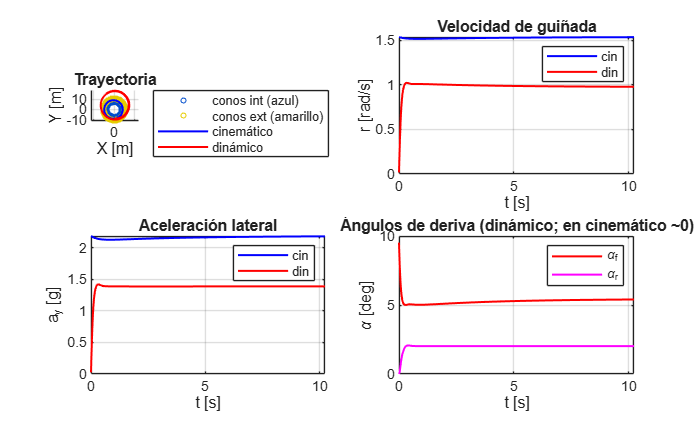

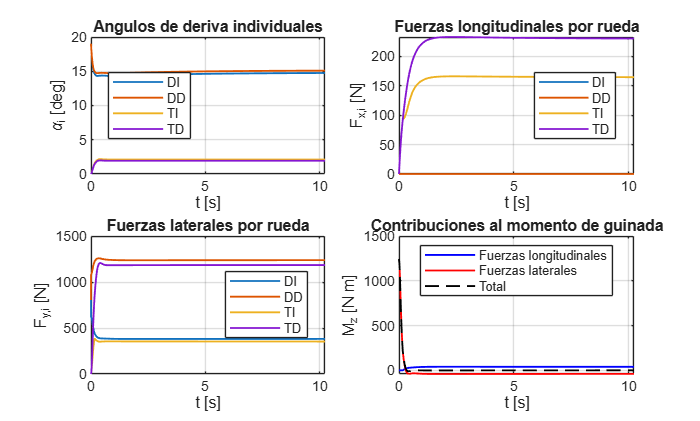

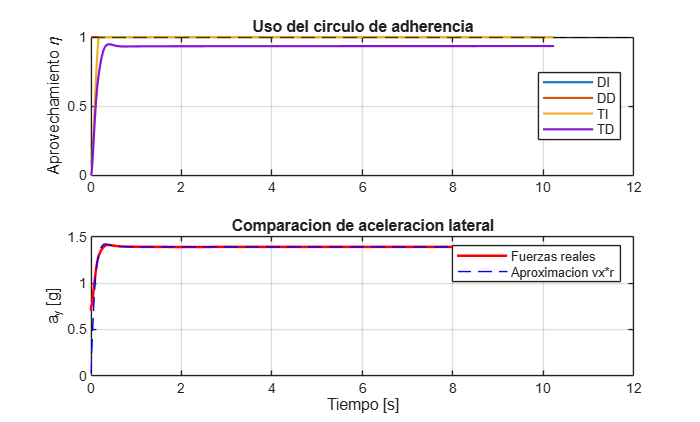

Aprovechamiento maximo por rueda:
    1.0000    1.0000    1.0000    0.9482

Aceleracion lateral maxima: 1.409 g

--- Resumen modelo 4 ruedas ---
Velocidad final: 13.95 m/s
Guiñada final: 0.977 rad/s
Max |deriva| por rueda [deg]: 19.04 19.04 2.17 1.98 
Max |Fx| por rueda [N]: 0.0 0.0 165.6 232.3 
Max |Fy| por rueda [N]: 803.8 1258.1 386.8 1206.8 


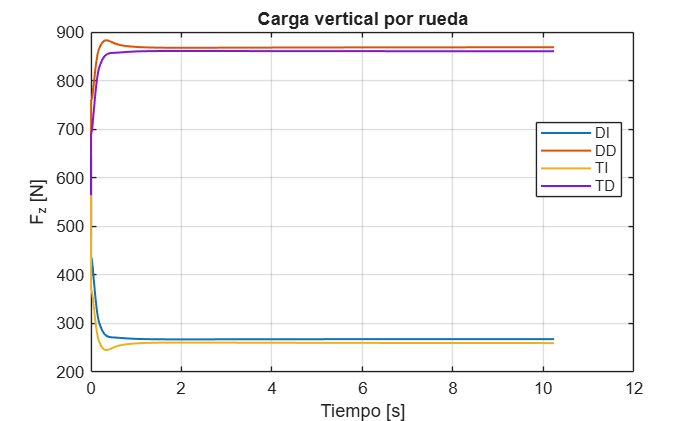

%% RESULTADOS DEL SKIDPAD

% Llamada al subprograma de resultados

Simulacion_skidpad(histCin, histDin, p, geom, Rcin, Rdin, @informarVueltas);

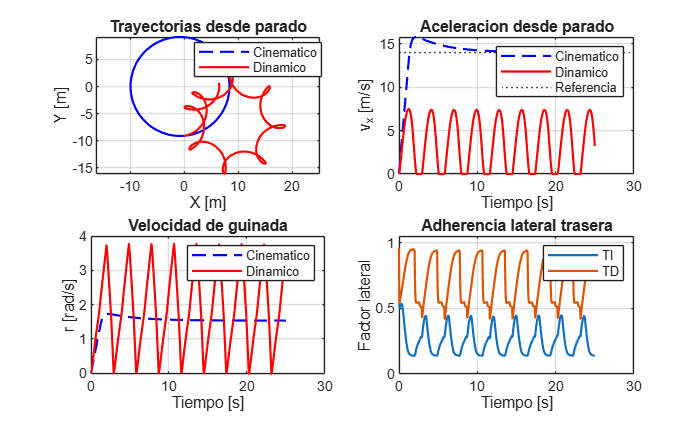


--- SKIDPAD DESDE PARADO ---
Reduccion lateral maxima: 86.2 %



%% SKIDPAD DESDE PARADO

[histSkid0Cin, histSkid0Din] = Simulacion_skidpad_parado(p, ctrl, geom, dt, @simularE2, @pasoCinematico, @pasoDinamico);

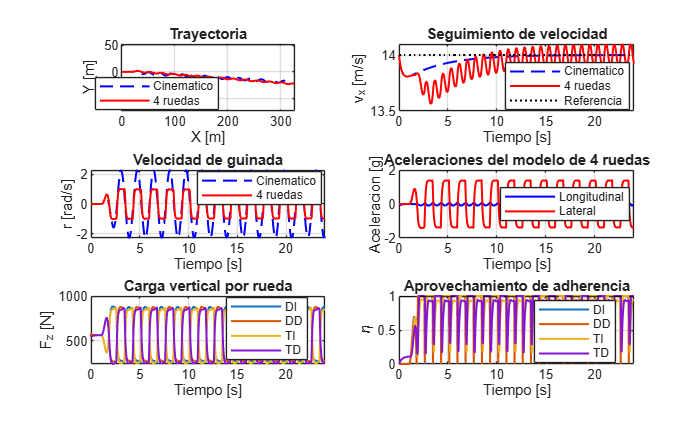

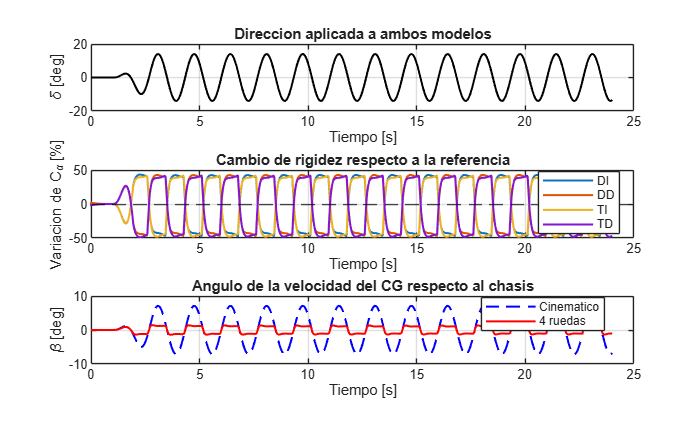


--- Eslalon ---
Carga minima por rueda [N]:
  253.4568  253.4403  248.1875  243.8460

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 87.3 %
Error maximo de equilibrio vertical: 0.000e+00 N



%% ESLALON

[histEslalonCin, histEslalonDin] = Simulacion_eslalon(p, ctrl, @simularManiobra, @mostrarManiobra);

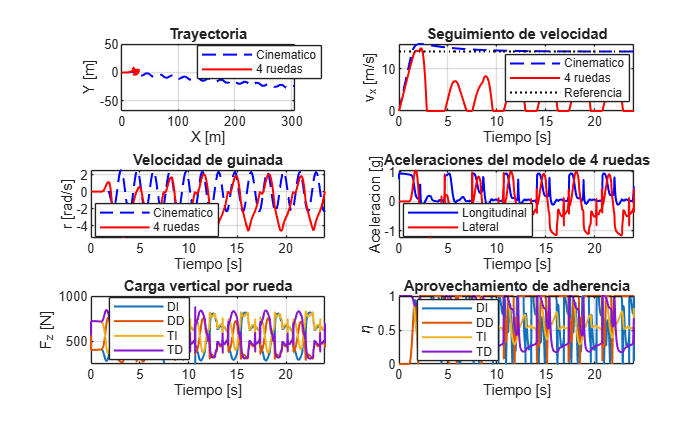

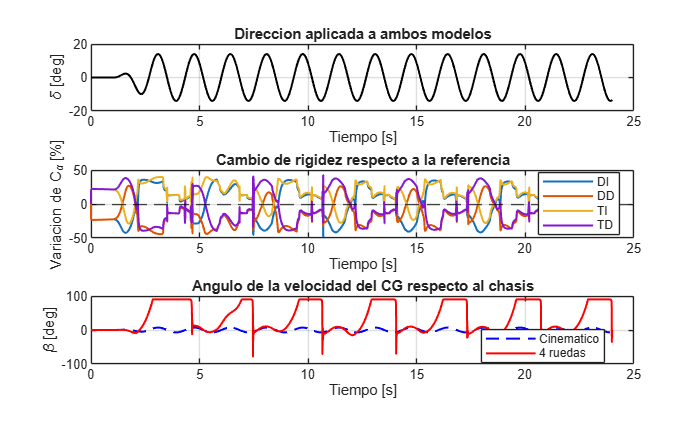


--- Eslalon desde parado ---
Carga minima por rueda [N]:
  249.8709  271.4997  368.3012  299.2440

Maximo aprovechamiento por rueda:
    1.0000    1.0000    1.0000    1.0000

Tiempo con alguna rueda saturada: 100.0 %
Error maximo de equilibrio vertical: 4.547e-13 N


%% ESLALON DESDE PARADO

[histEslalon0Cin, histEslalon0Din] = Simulacion_eslalon_parado(p, ctrl, @simularManiobra, @mostrarManiobra);

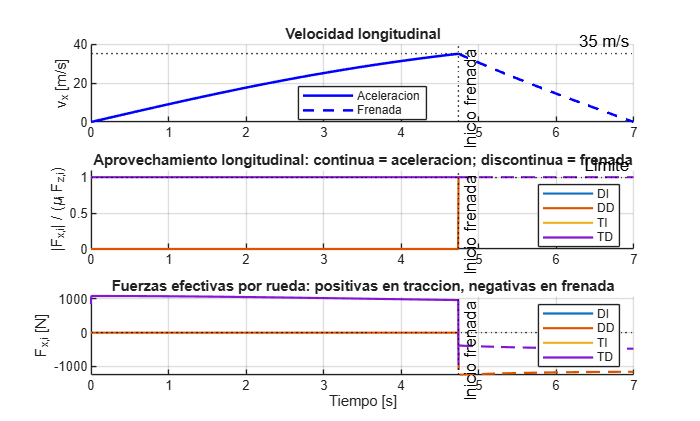


--- ACELERACION Y FRENADA EN RECTA ---
Velocidad maxima registrada: 35.002 m/s
Tiempo acelerando: 4.738 s
Tiempo de frenada registrado: 2.256 s
Distancia de frenada: 38.053 m
Velocidad final: 0.0000 m/s
Saturacion no equivale a bloqueo: no se modela rotacion de ruedas.
Las curvas izquierda/derecha coinciden por simetria en recta.


histRecta = Simulacion_aceleracion_frenada(p, dt, @pasoDinamico);


function hist = simularManiobra(p, ctrl, dt, caso, tipo, dinamico)

N = round(caso.T/dt);
z = [0; 0; 0; caso.v0; 0; 0];

e_int = 0;
ax_prev = 0;
ay_prev = 0;
eta_prev = ones(1,4);

hist.t = (0:N-1)'*dt;
hist.z = zeros(N,6);
hist.vref = zeros(N,1);
hist.delta = zeros(N,1);
hist.Fx_cmd = zeros(N,1);

if dinamico
    hist.Fzw = zeros(N,4);
    hist.Caw = zeros(N,4);
    hist.eta = zeros(N,4);
    hist.ax = zeros(N,1);
    hist.ay = zeros(N,1);
    hist.lambda_w = zeros(N,4);
    hist.s_w = zeros(N,4);
    hist.eta_slip = ones(N,4);
end

for k = 1:N
    t = hist.t(k);

    if tipo == 1
        % Entrada en curva entre 1 y 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = caso.delta*entrada;

        % 0-4 s: 5 m/s
        % 4-8 s: subida progresiva hasta 8 m/s
        % 8-11 s: 8 m/s
        % 11-14 s: bajada progresiva hasta 5 m/s
        % 14-20 s: 5 m/s
        subida = min(max((t-4)/4,0),1);
        bajada = min(max((t-11)/3,0),1);

        vref = 5 + 3*subida - 3*bajada;

    else
        % Entrada suave al eslalon entre 1 y 3 s
        s = min(max((t-1)/2,0),1);
        entrada = s^2*(3-2*s);

        delta = entrada*caso.amplitud * sin(2*pi*caso.frecuencia*(t-1));

        
        % Velocidad de referencia independiente de la inicial
        if isfield(caso,'vobjetivo')
            vref = caso.vobjetivo;
        else
            vref = caso.v0;
        end

    end

    [Fx, e_int] = controlLongitudinal(vref, z(4), e_int, dt, ctrl, p);

    u = [Fx; delta];

    % Estados e inputs al inicio del paso
    hist.z(k,:) = z.';
    hist.vref(k) = vref;
    hist.delta(k) = delta;
    hist.Fx_cmd(k) = Fx;

    if dinamico
        [z_next, tele] = pasoDinamico(z, u, p, dt, ax_prev, ay_prev, eta_prev);

        hist.Fzw(k,:) = tele.Fzw;
        hist.Caw(k,:) = tele.Caw;

        hist.eta(k,:) = hypot(tele.Fxw,tele.Fyw)./ max(tele.Fmax_w,eps);

        hist.ax(k) = tele.ax;
        hist.ay(k) = tele.ay;
        hist.lambda_w(k,:) = tele.lambda_w;
        hist.s_w(k,:) = tele.s_w;
        hist.eta_slip(k,:) = tele.eta_slip;
        eta_prev = tele.eta_slip;

        ax_prev = tele.ax;
        ay_prev = tele.ay;

    else
        z_next = pasoCinematico(z, u, p, dt);
    end

    z = z_next;
end
end
function mostrarManiobra(cin, din, p, nombre)

t = din.t;
ruedas = {'DI','DD','TI','TD'};

figure('Name',nombre,'Color','w');

subplot(3,2,1)
plot(cin.z(:,1),cin.z(:,2),'b--', ...
    din.z(:,1),din.z(:,2),'r','LineWidth',1.2);
axis equal; grid on;
xlabel('X [m]'); ylabel('Y [m]');
title('Trayectoria');
legend('Cinematico','4 ruedas','Location','best');

subplot(3,2,2)
plot(t,cin.z(:,4),'b--', ...
    t,din.z(:,4),'r', ...
    t,din.vref,'k:','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('v_x [m/s]');
title('Seguimiento de velocidad');
legend('Cinematico','4 ruedas','Referencia','Location','best');

subplot(3,2,3)
plot(t,cin.z(:,6),'b--', ...
    t,din.z(:,6),'r','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('r [rad/s]');
title('Velocidad de guinada');
legend('Cinematico','4 ruedas','Location','best');

subplot(3,2,4)
plot(t,din.ax/p.g,'b', ...
    t,din.ay/p.g,'r','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('Aceleracion [g]');
title('Aceleraciones del modelo de 4 ruedas');
legend('Longitudinal','Lateral','Location','best');

subplot(3,2,5)
plot(t,din.Fzw,'LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('F_z [N]');
title('Carga vertical por rueda');
legend(ruedas,'Location','best');

subplot(3,2,6)
plot(t,din.eta,'LineWidth',1.2);
yline(1,'k--','Limite');
grid on;
xlabel('Tiempo [s]'); ylabel('\eta');
title('Aprovechamiento de adherencia');
legend(ruedas,'Location','best');

% Segunda figura: entrada y respuesta de los neumaticos
figure('Name',[nombre ' - Direccion y rigidez'],'Color','w');

subplot(3,1,1)
plot(t,rad2deg(din.delta),'k','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('\delta [deg]');
title('Direccion aplicada a ambos modelos');

subplot(3,1,2)
plot(t,100*(din.Caw./p.Caw - 1),'LineWidth',1.2);
yline(0,'k--');
grid on;
xlabel('Tiempo [s]'); ylabel('Variacion de C_\alpha [%]');
title('Cambio de rigidez respecto a la referencia');
legend(ruedas,'Location','best');

subplot(3,1,3)
betaCin = atan2(cin.z(:,5),cin.z(:,4));
betaDin = atan2(din.z(:,5),din.z(:,4));

plot(t,rad2deg(betaCin),'b--', t,rad2deg(betaDin),'r','LineWidth',1.2);
grid on;
xlabel('Tiempo [s]'); ylabel('\beta [deg]');
title('Angulo de la velocidad del CG respecto al chasis');
legend('Cinematico','4 ruedas','Location','best');

fprintf('\n--- %s ---\n',nombre);
fprintf('Carga minima por rueda [N]:\n');
disp(min(din.Fzw,[],1));

fprintf('Maximo aprovechamiento por rueda:\n');
disp(max(din.eta,[],1));

fprintf('Tiempo con alguna rueda saturada: %.1f %%\n', 100*mean(any(din.lambda_w < 1-1e-6,2)));

fprintf('Error maximo de equilibrio vertical: %.3e N\n', max(abs(sum(din.Fzw,2)-p.m*p.g)));
end

Como vemos el modelo cinemático traza un círculo de radio constante al no tener deriva, mientras que el modelo dinámico traza un círculo ligeramente mayor con el mismo ángulo de giro del volante debido al subviraje del vehículo. Ambos experimentan una fuerza lateral de aproximadamente 0.55g. 

⚡ En Formula Student, el tiempo en el skidpad mide la aceleración lateral máxima del monoplaza. En la industria del automóvil, los ensayos de radio constante sirven además para medir el **gradiente de subviraje**.